# PDSCH资源映射

PDSCH代表物理下行共享信道（Physical Downlink Shared Channel），是在5G无线通信系统中用于传输下行数据的一种物理信道。

**PDSCH调度的关键参数**

- 调制与编码方案（Modulation and Coding Scheme，MCS）

- 时域资源表格和RB位置；

- DMRS配置和port指示；

- 速率匹配pattern配置（RB级/RE级）。

## 1 载波配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 51;                % Size of carrier in RB

## 2 PDSCH资源配置

% PDSCH configuration
pdsch = nrPDSCHConfig;

% BWP
pdsch.NStartBWP = [];
pdsch.NSizeBWP = [];

% Ratematch pattern
pdschReserved = nrPDSCHReservedConfig;
pdschReserved.PRBSet = [];
pdschReserved.SymbolSet = [];
pdschReserved.Period = [];
pdsch.ReservedPRB = {pdschReserved};
pdsch.ReservedRE = [];

% AMC, RB Allocation
pdsch.Modulation = '256QAM';
pdsch.NumLayers = 4;
pdsch.MappingType = 'A';
pdsch.SymbolAllocation = [1,13];
pdsch.PRBSet = 0;

% PDSCH Interleave
pdsch.VRBToPRBInterleaving = 0;
pdsch.VRBBundleSize = 2;

% PDSCH scrambling identity and RNTI
pdsch.RNTI = 1;
pdsch.NID = []; 

## 3 PDSCH DMRS配置

在NR协议中通过DCI1-1指示，对应bit位域为Antenna port，通过value指示【Number of DMRS CDM group(s) without data】和【DMRS port(s)】。在仿真系统里对应参数为NumCDMGroupsWithoutData和DMRSPortSet。

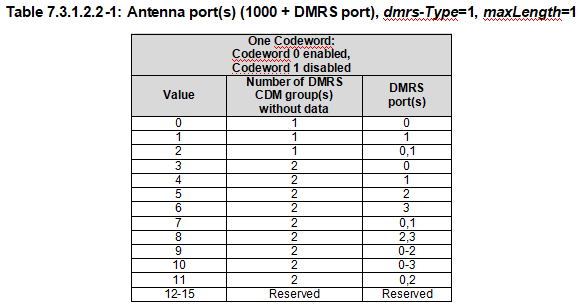

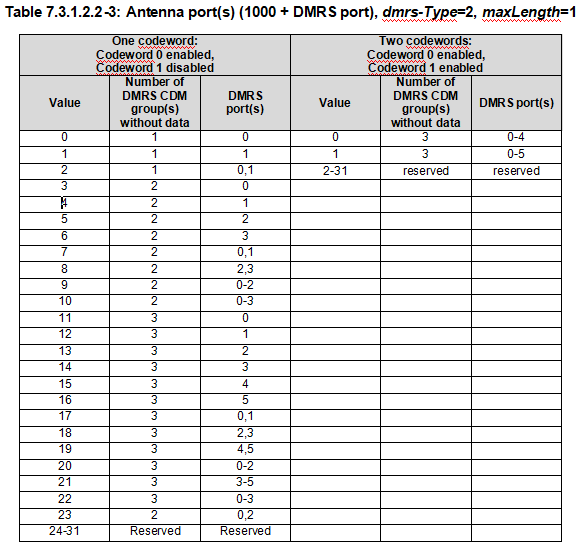

% PDSCH DMRS configuration
pdschDmrs = nrPDSCHDMRSConfig;
pdschDmrs.DMRSConfigurationType = 1;
pdschDmrs.DMRSReferencePoint = 'CRB0';
pdschDmrs.DMRSTypeAPosition = 2;
pdschDmrs.DMRSAdditionalPosition = 1;
pdschDmrs.DMRSLength = 1;
pdschDmrs.DMRSPortSet = [];   % [] implies that DMRSPortSet is in the range from 0 to NumLayers– 1.
pdschDmrs.NIDNSCID = [];
pdschDmrs.NSCID = 0;
pdschDmrs.NumCDMGroupsWithoutData = 2;   % type1: 1 2; type2: 1 2 3
pdsch.DMRS = pdschDmrs;

disp(pdschDmrs)

  nrPDSCHDMRSConfig - 属性:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 1
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]



## 3 资源映射

% Generate PDSCH DM-RS symbols
symDmrs = nrPDSCHDMRS(carrier,pdsch);
dmrsInd = nrPDSCHDMRSIndices(carrier,pdsch);

% Generate PDSCH symbols
[symInd,info] = nrPDSCHIndices(carrier,pdsch);
numDataBits = info.G;
cws = randi([0 1],numDataBits,1);
symPdsch = nrPDSCH(carrier,pdsch,cws);

carrierGrid = nrResourceGrid(carrier,pdsch.NumLayers);
carrierGrid(symInd) = symPdsch;
carrierGrid(dmrsInd) = symDmrs;

disp(info)

                G: 4224
               Gd: 132
        NREPerPRB: 132
    DMRSSymbolSet: [2 11]
    PTRSSymbolSet: [1×0 double]



**对资源网格画图显示**

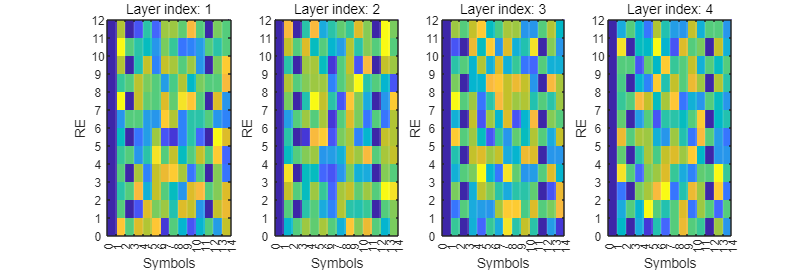

fig = figure;
fig.Position = [100 100 1200 400];
for idx = 1:pdsch.NumLayers
    subplot(1,4,idx)
    imagesc(abs(carrierGrid(:,:,idx)));
    set(gca, 'XLim', [0.5, 14.5]);
    set(gca, 'XTick', (0:14)+0.5);
    set(gca, 'XTickLabel', (0:14));
    set(gca, 'XGrid', 'on');
    set(gca, 'GridColor', 'white');
    set(gca, 'YDir', 'normal');
    set(gca, 'YLim', [0.5, 12.5]);
    set(gca, 'YTick', (0:12)+0.5);
    set(gca, 'YTickLabel', (0:12));
    xlabel('Symbols');
    ylabel('RE');
    title(['Layer index: ',num2str(idx)])
end